clear;
close all;
clc;

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

## **NETWORK PARAMETERS**

N_BLK = 1000;

M = 100;
K = 4;

B = 8;
M_QAM = 2^B;

SNR = -10:1:20;
N_SNR = length(SNR);

H = (randn(M, K) + 1i * randn(M, K)) / sqrt(2);

## MEMORY ALLOCATION

s = zeros(N_BLK, K);

BER_ZF = zeros(1, N_SNR);
BER_MF = zeros(1, N_SNR);
BER_ZF_clipped = zeros(1, N_SNR);
BER_MF_clipped = zeros(1, N_SNR);

bit_array = randi([0,1], B*N_BLK, K);

## CLIPPING FUNCTION

A0 = 1;
clip = @(x, A0) min(abs(x), A0) .* exp(1j * angle(x));

## QAM MODULATION AND PRECODING

% QAM Modulation
for users_idx = 1:K
    s(:, users_idx) = qammod(bit_array(:, users_idx), M_QAM, 'InputType', 'bit');
end

% Precoders
precoder_ZF = conj(H) / (H.' * conj(H));
precoder_MF = conj(H) ./ (vecnorm(H).^2);

% TX
x_ZF = precoder_ZF * s.';
x_MF = precoder_MF * s.';

x_ZF_normalized = zeros(size(x_ZF)); 
x_MF_normalized = zeros(size(x_MF));

% Normalization of signals
for i = 1:size(x_ZF, 1)
    Px_ZF = abs(x_ZF(i, :)).^2;
    Px_MF = abs(x_MF(i, :)).^2;
    
    x_ZF_normalized(i, :) = x_ZF(i, :) / sqrt(Px_ZF);
    x_MF_normalized(i, :) = x_MF(i, :) / sqrt(Px_MF);
end

% Clipping
x_ZF_clipped = clip(x_ZF_normalized, A0);
x_MF_clipped = clip(x_MF_normalized, A0);

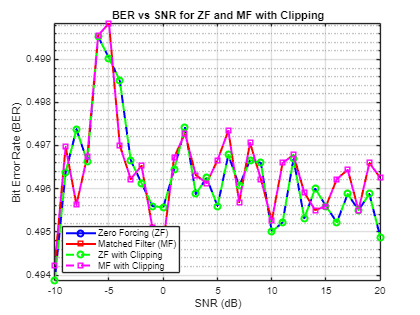

% Simulação de BER para diferentes valores de SNR
for snr_idx = 1:N_SNR
    snr = 10^(SNR(snr_idx)/10);
    noise_variance = 1/snr;
    v = sqrt(noise_variance/2) * (randn(size(H,2), N_BLK) + 1i*randn(size(H,2), N_BLK));

    y_ZF = H.' * x_ZF_normalized + v;
    y_MF = H.' * x_MF_normalized + v;
    
    % Demodulação e cálculo da BER para ZF
    bit_received_ZF = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_ZF = y_ZF(users_idx, :).';
        bit_received_ZF(:, users_idx) = qamdemod(s_received_ZF, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_ZF = sum(bit_array ~= bit_received_ZF, 'all');
    BER_ZF(snr_idx) = bit_errors_ZF / numel(bit_array);

    % Demodulação e cálculo da BER para MF
    bit_received_MF = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_MF = y_MF(users_idx, :).';
        bit_received_MF(:, users_idx) = qamdemod(s_received_MF, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_MF = sum(bit_array ~= bit_received_MF, 'all');
    BER_MF(snr_idx) = bit_errors_MF / numel(bit_array);

    % Demodulação e cálculo da BER para ZF com clipping
    y_ZF_clipped = H.' * x_ZF_clipped + v;
    bit_received_ZF_clipped = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_ZF_clipped = y_ZF_clipped(users_idx, :).';
        bit_received_ZF_clipped(:, users_idx) = qamdemod(s_received_ZF_clipped, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_ZF_clipped = sum(bit_array ~= bit_received_ZF_clipped, 'all');
    BER_ZF_clipped(snr_idx) = bit_errors_ZF_clipped / numel(bit_array);

    % Demodulação e cálculo da BER para MF com clipping
    y_MF_clipped = H.' * x_MF_clipped + v;
    bit_received_MF_clipped = zeros(B*N_BLK, K);
    for users_idx = 1:K
        s_received_MF_clipped = y_MF_clipped(users_idx, :).';
        bit_received_MF_clipped(:, users_idx) = qamdemod(s_received_MF_clipped, M_QAM, 'OutputType', 'bit');
    end
    bit_errors_MF_clipped = sum(bit_array ~= bit_received_MF_clipped, 'all');
    BER_MF_clipped(snr_idx) = bit_errors_MF_clipped / numel(bit_array);
end
% BER vs SNR
figure;
semilogy(SNR, BER_ZF, 'o-', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b'); hold on;
semilogy(SNR, BER_MF, 's-', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'r');
semilogy(SNR, BER_ZF_clipped, 'o--', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'g');
semilogy(SNR, BER_MF_clipped, 's--', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'm');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
legend('Zero Forcing (ZF)', 'Matched Filter (MF)', 'ZF with Clipping', 'MF with Clipping', 'Location', 'southwest');
title('BER vs SNR for ZF and MF with Clipping');
hold off;